%doc_struct.ruru.preproc_text = strings(size(doc_struct.ruru.transcript));

doc_struct.ruru.preproc_text = preprocessText(doc_struct.ruru.transcript);

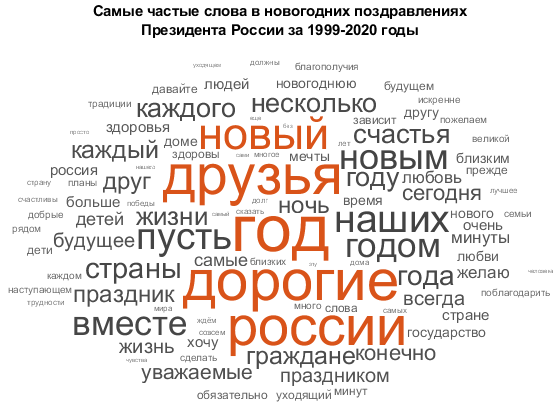


remove_word_arr = [
    "что" "для" "нас" "вас" "всё" "все" "они" "эти" "это" "всем" "всех" "сейчас" ...
    "кто" "как" "нам" "вам" "его" "этот" "нам" "был" "через" "только" "своих" "этом" ...
    "чтобы" "тех" "когда" "всего" "наша" "себя" "будем" "наши" "уже" "вами" "были" "вами" ...
    "свои" "этого" "своим" "нашей" "того" "где" "быть" "было" "своей" "них" "быть" "было" ...
    "будет" "том" "тем" "которые" "будут" 
];

doc_struct.ruru.preproc_text = removeWords(doc_struct.ruru.preproc_text, remove_word_arr);

doc_struct.ruru.tokenized = tokenizedDocument(doc_struct.ruru.preproc_text);

doc_struct.ruru.bag = bagOfWords(doc_struct.ruru.preproc_text);

wordcloud(doc_struct.ruru.bag);

title({'Самые частые слова в новогодних поздравлениях', ...
    'Президента России за 1999-2020 годы'})

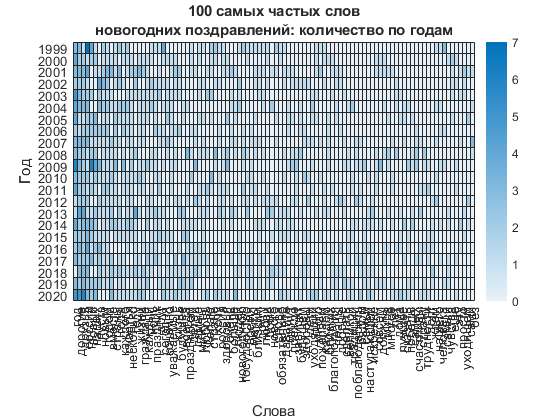

% top 100 words data by years for heat map 
top100 = topkwords(doc_struct.ruru.bag, 100);

top100_vocab_idx = zeros(100, 1);

for i = 1:100
    top100_vocab_idx(i, 1) = find(doc_struct.ruru.bag.Vocabulary == top100.Word(i));
end

heatmap(doc_struct.ruru.bag.Counts(:, top100_vocab_idx));
ax=gca;
ax.XData = doc_struct.ruru.bag.Vocabulary(top100_vocab_idx);
ax.YData = 1999:2020;

title({'100 самых частых слов', ...
    'новогодних поздравлений: количество по годам'});

xlabel('Слова');
ylabel('Год');

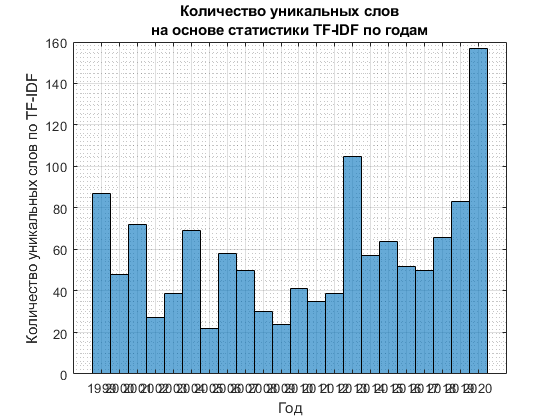

% tf-idf features
tf_idf = tfidf(doc_struct.ruru.bag,'TFWeight','binary');

% find elements with max TF-IDF score
[row, col, val] = find(2.5 < tf_idf);

histogram(row, 'BinMethod', 'integers');
xticks(1:22);
xticklabels(1999:2020);

grid on;
grid minor;

xlabel('Год');
ylabel('Количество уникальных слов по TF-IDF');
title({'Количество уникальных слов', ...
    'на основе статистики TF-IDF по годам'})

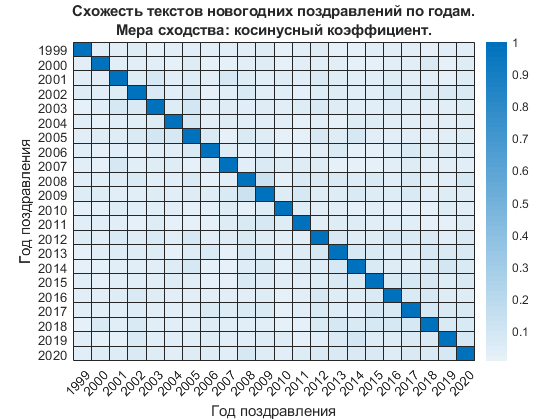

% cosine similarity
cos_sim = cosineSimilarity(doc_struct.ruru.bag);

heatmap(cos_sim);
xlabel('Год поздравления');

ylabel('Год поздравления');

ax=gca;
ax.XData = doc_struct.ruru.year;
ax.YData = doc_struct.ruru.year;

title({'Схожесть текстов новогодних поздравлений по годам.', ...
    'Мера сходства: косинусный коэффициент.'});